%% Clear temporary variables
clear variables

# **2D Example - Chloride Concentrations in Baden-Wuerttemberg**

**Description:** This script loads and processes the chloride concentrations dataset, which exhibits strong rank asymmetry and a small directional asymmetry. Various statistical analyses are performed, including the calculation of directional asymmetry, rank asymmetry, and variograms. The results are visualized using plots to interpret the directional properties and spatial characteristics of the dataset.

**Set Up Simulation Parameters**

This section outlines the parameters used for simulating the random fields and performing the computations.

%% Import data from text file
%    filename: E4 - Chroride\chloride_gridded.dat
Z = table2array(readtable("E4 - Chroride\chloride_gridded.dat"));

%% Counting the number of nan
nbdata = sum(~isnan(Z),'all') ;

%% Generate the grid
[nx, ny ] = size(Z);
x0 = grille2(1,nx,1,1,ny,1);

%% Processing Z
Z = reshape(Z,[],1);
Y = Z;
Z = ECDF(Z);
Z(Z==0) = nan;

## Display the dataset

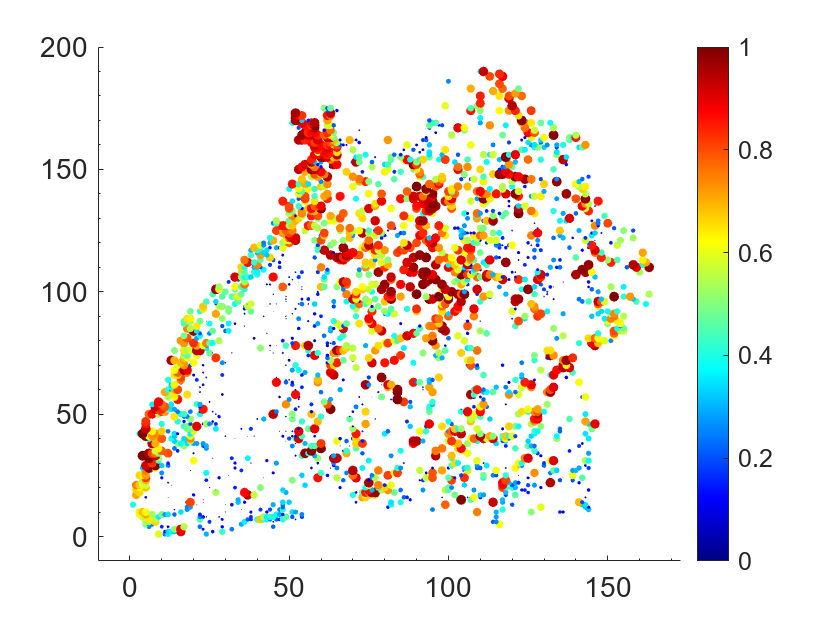

%% Scatter plot of data
idx = ~isnan(Z);
figure(10)
scatter(x0(~isnan(Z),1), x0(~isnan(Z),2), Z(~isnan(Z))*25, Z(~isnan(Z)), 'filled')
colorbar();
colormap 'jet'
clim([0 1])
xlim([-10 nx+10])
ylim([-10 ny+10])
fontsize(gca, 14, 'points')
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')

**Compute the directional asymmetry**

This section calculates the directional asymmetry of the chloride concentration dataset. The data is classified as non-categorical by setting `categ = 0`, and visualization is disabled with `display = 0`. The field is transformed into rank values by specifying `rank = 1`, while the operation for calculating directional asymmetry is defined with `icode = 8`.

Next, 100 Gaussian random fields (GRFs) with the same variogram as the dataset are simulated using the `fftma` function. For each realization, the directional asymmetry is calculated with `GeoStatFFT`, and the results are stored in `gh1`.

The results are visualized in Figure 42, where the asymmetry values for each GRF realization are shown as light gray lines. The mean asymmetry is represented by a bold black line, with dashed lines marking the 5th and 95th percentiles. We used `GeoStatFFT_ndir` to compute the experimental directional asymmetry in multiple directions: azimuths of 0°, 22.5°, 45°, 67.5°, 90°, 112.5°, 135°, and 157.5°, with an angular tolerance of 10°. A maximum distance of 40 pixels with 10 equidistant classes was used. The `GeoStatFFT_ndir` results are plotted as red dots.

The plot includes labels for the x-axis ("Distance") and y-axis ("Directional Asymmetry Value"), as well as a legend. Axis limits and minor ticks have been adjusted for improved readability

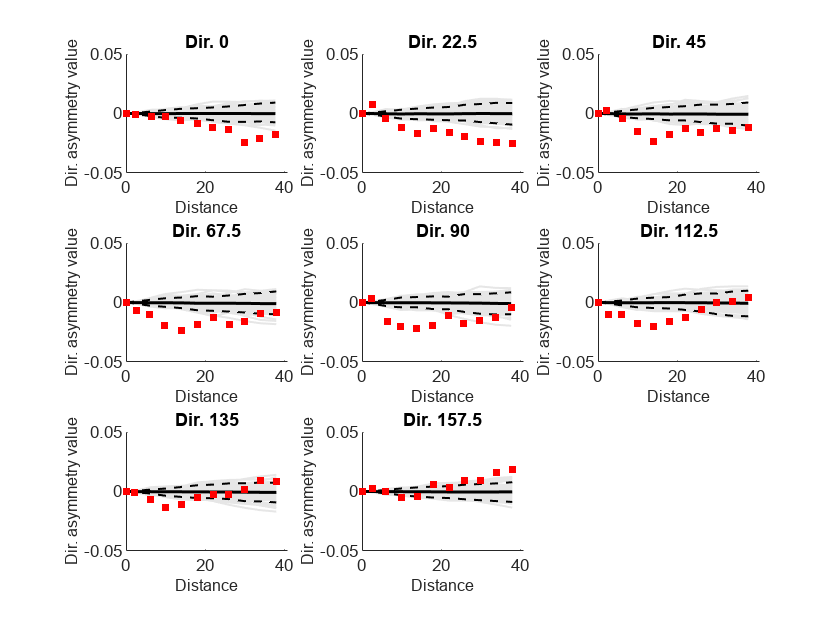

%% Compute directional asymmetry
categ = 0;
display = 0;
icode = 8;
rank = 1 ;

[gh, nh]=GeoStatFFT(x0,Z,icode,categ,display,rank);

nbdist= 10;
ang=[0,1,2,3,4,5,6,7]'*22.5;
tol_ang = 10;
max_dist = 40;
dist = [(0:nbdist-1);(1:nbdist)]'*(max_dist/nbdist);

[gh_dir, nh_dir, lag_dir] = GeoStatFFT_ndir(gh, nh, dist, ang, tol_ang);

% Simulation of random fields
[z]=fftma([2 3 6 157.5 ],0.2,45124241,100,nx,1,ny,1);
display = 0 ;
for i =1:100
    [gh1{i}, nh1{i}] = GeoStatFFT(x0,z(:,i),icode,categ,display,rank);
    [gh1_dir{i}, nh1_dir{i}, lag1_dir{i}] = GeoStatFFT_ndir(gh1{i}, nh1{i}, dist, ang, tol_ang);
end

figure(42)
ii=1; j=1;
for k = 1: length(ang)
    subplot(3, 3, k)
    hold on
    for i=1:100
        plot(lag1_dir{i}{ii,j}(:,k), gh1_dir{i}{ii,j}(:,k),'color', [0.9 0.9 0.9], LineWidth=1)
        hold on
        gmean(:,i) = gh1_dir{i}{ii,j}(:,k);
    end
    plot(lag1_dir{i}{ii,j}(:,k),mean(gmean,2), '-k',LineWidth=1.5)
    hold on
    plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.05,2),'--k',LineWidth=1)
    hold on
    plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.95,2),'--k',LineWidth=1)
    hold on
    plot(lag_dir{ii,j}(:,k), gh_dir{ii,j}(:,k), 'sr',MarkerEdgeColor='red',MarkerFaceColor='red', MarkerSize= 4)
    %t = text(lag_dir{ii,j}(:,k) + 0.005, gh_dir{ii,j}(:,k) + 0.005, string(nh_dir{ii,j}(:,k)));
    % Adjust font size for each text element
    %for kk = 1:length(t)
    %    t(kk).FontSize = 10;
    %    t(kk).Rotation = 60;
    %end

    xlim([0, round(nx / 4)]);
    ylim([-0.05, 0.05]);
    title(['Dir. ', num2str(ang(k))]);
        xlabel('Distance','FontSize',8)
    ylabel('Dir. asymmetry value','FontSize',8)
    
end
% Save the figure as an EPS file with consistent font sizes
print('E4 - Chroride/DirAssExp', '-depsc'); % Replace 'your_figure_name' with your desired filename

**Compute the bivariate (or rank) asymmetry**

We generate the same graph but set `icode = 7` to calculate rank asymmetry.

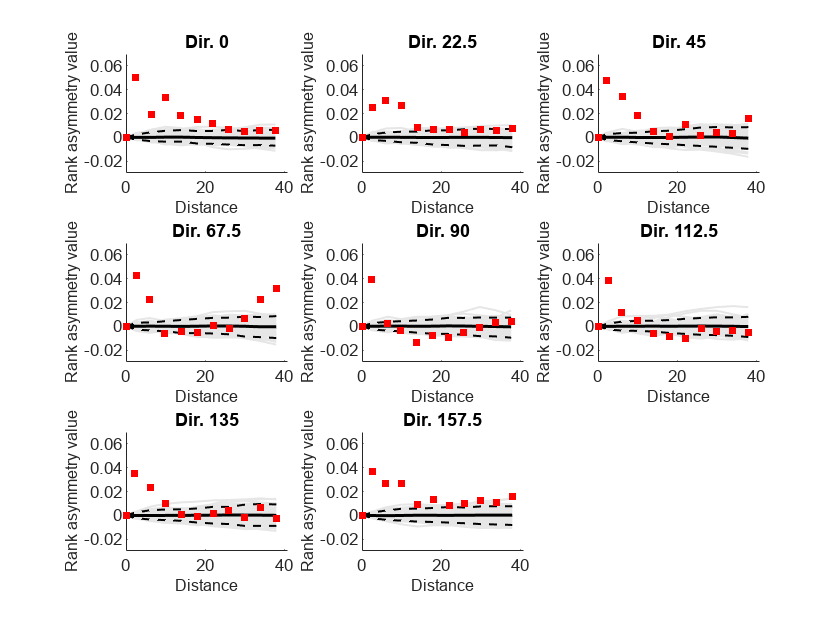

categ = 0;
display = 0;
icode = 9;
rank = 1 ;

[gh, nh]=GeoStatFFT(x0,Z,icode,categ,display,rank);

nbdist= 10;
ang=[0,1,2,3,4,5,6,7]'*22.5;
tol_ang = 10;
max_dist = 40;
dist = [(0:nbdist-1);(1:nbdist)]'*(max_dist/nbdist);

[gh_dir, nh_dir, lag_dir] = GeoStatFFT_ndir(gh, nh, dist, ang, tol_ang);

% Simulation of random fields
[z]=fftma([2 3 6 157.5 ],0.2,45124241,100,nx,1,ny,1);
display = 0 ;
for i =1:100
    [gh1{i}, nh1{i}] = GeoStatFFT(x0,z(:,i),icode,categ,display,rank);
    [gh1_dir{i}, nh1_dir{i}, lag1_dir{i}] = GeoStatFFT_ndir(gh1{i}, nh1{i}, dist, ang, tol_ang);
end

figure(47)
ii=1; j=1;
for k = 1: length(ang)
    subplot(3, 3, k)
    hold on
    for i=1:100
        plot(lag1_dir{i}{ii,j}(:,k), gh1_dir{i}{ii,j}(:,k),'color', [0.9 0.9 0.9], LineWidth=1)
        hold on
        gmean(:,i) = gh1_dir{i}{ii,j}(:,k);
    end
    plot(lag1_dir{i}{ii,j}(:,k),mean(gmean,2), '-k',LineWidth=1.5)
    hold on
    plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.05,2),'--k',LineWidth=1)
    hold on
    plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.95,2),'--k',LineWidth=1)
    hold on

    plot(lag_dir{ii,j}(:,k), gh_dir{ii,j}(:,k), 'sr',MarkerEdgeColor='red',MarkerFaceColor='red', MarkerSize= 4)
    %t = text(lag_dir{ii,j}(:,k) + 0.005, gh_dir{ii,j}(:,k) + 0.005, string(nh_dir{ii,j}(:,k)));
    % Adjust font size for each text element
    %for kk = 1:length(t)
    %    t(kk).FontSize = 10;
    %    t(kk).Rotation = 60;
    %end

    xlim([0, round(nx / 4)]);
    ylim([-0.03, 0.07]);
    title(['Dir. ', num2str(ang(k))]);
        xlabel('Distance','FontSize',8)
    ylabel('Rank asymmetry value','FontSize',8)
    
end
% Save the figure as an EPS file with consistent font sizes
print('E4 - Chroride/RankAssExp', '-depsc'); % Replace 'your_figure_name' with your desired filename

**Compute rank correlation**

We generate the same graph but set `icode = 10` to calculate rank correlation.

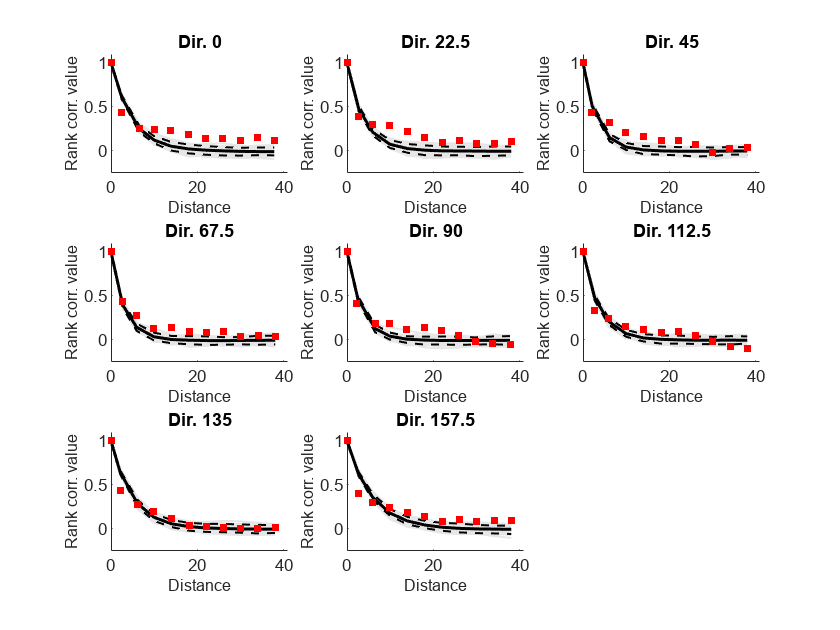

categ = 0;
display = 0;
icode = 10;
rank = 1 ;

[gh, nh]=GeoStatFFT(x0,Z,icode,categ,display,rank);

nbdist= 10;
ang=[0,1,2,3,4,5,6,7]'*22.5;
tol_ang = 10;
max_dist = 40;
dist = [(0:nbdist-1);(1:nbdist)]'*(max_dist/nbdist);
[gh_dir, nh_dir, lag_dir] = GeoStatFFT_ndir(gh, nh, dist, ang, tol_ang);

% Simulation of random fields
[z]=fftma([2 3 6 157.5 ],0.2,45124241,100,nx,1,ny,1);
display = 0 ;
for i =1:100
    [gh1{i}, nh1{i}] = GeoStatFFT(x0,z(:,i),icode,categ,display,rank);
    [gh1_dir{i}, nh1_dir{i}, lag1_dir{i}] = GeoStatFFT_ndir(gh1{i}, nh1{i}, dist, ang, tol_ang);
end

figure(50)
ii=1; j=1;
for k = 1: length(ang)
    subplot(3, 3, k)
    hold on
    for i=1:100
        plot(lag1_dir{i}{ii,j}(:,k), gh1_dir{i}{ii,j}(:,k),'color', [0.9 0.9 0.9], LineWidth=1)
        hold on
        gmean(:,i) = gh1_dir{i}{ii,j}(:,k);
    end
    plot(lag1_dir{i}{ii,j}(:,k),mean(gmean,2), '-k',LineWidth=1.5)
    hold on
    plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.05,2),'--k',LineWidth=1)
    hold on
    plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.95,2),'--k',LineWidth=1)
    hold on
    plot(lag_dir{ii,j}(:,k), gh_dir{ii,j}(:,k), 'sr',MarkerEdgeColor='red',MarkerFaceColor='red', MarkerSize= 4)
    %t = text(lag_dir{ii,j}(:,k) + 0.05, gh_dir{ii,j}(:,k) + 0.05, string(nh_dir{ii,j}(:,k)));
    % Adjust font size for each text element
    %for kk = 1:length(t)
    %    t(kk).FontSize = 10;
    %    t(kk).Rotation = 60;
    %end

    xlim([0, round(nx / 4)]);
    ylim([-0.25, 1.1]);
    title(['Dir. ', num2str(ang(k))]);
    xlabel('Distance','FontSize',8)
    ylabel('Rank corr. value','FontSize',8)
end
% Save the figure as an EPS file with consistent font sizes
print('E4 - Chroride/RankCorExp', '-depsc'); % Replace 'your_figure_name' with your desired filename

**Compute Variogram**

We generate the same graph but set `icode = 1` to calculate variogram.

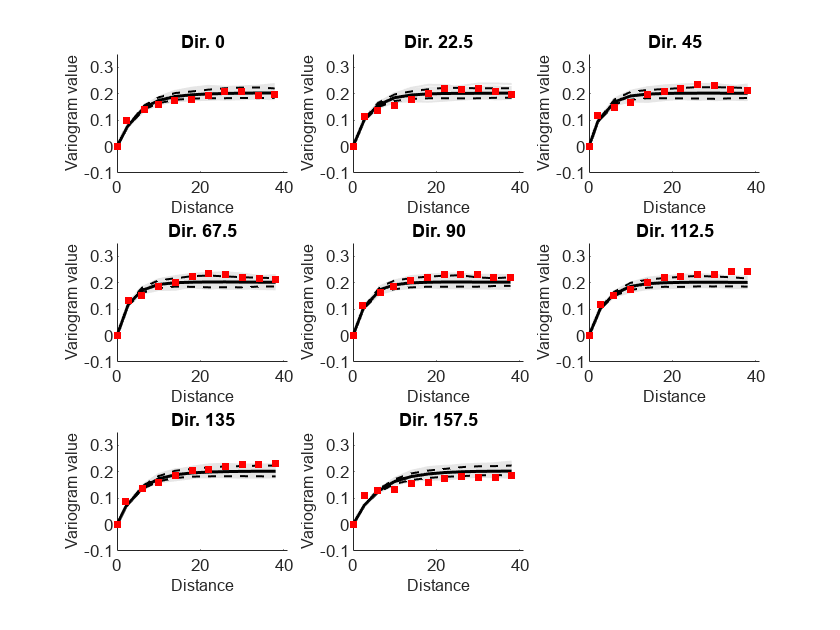

categ = 0;
display = 0;
icode = 1;
rank = 0 ;


[gh, nh]=GeoStatFFT(x0,log10(Y),icode,categ,display,rank);

nbdist= 10;
ang=[0,1,2,3,4,5,6,7]'*22.5;
tol_ang = 10;
max_dist = 40;
dist = [(0:nbdist-1);(1:nbdist)]'*(max_dist/nbdist);

[gh_dir, nh_dir, lag_dir] = GeoStatFFT_ndir(gh, nh, dist, ang, tol_ang);

% Simulation of random fields
[z]=fftma([2 3 6 157.5 ],0.2,45124241,100,nx,1,ny,1);
display = 0 ;
for i =1:100
    [gh1{i}, nh1{i}] = GeoStatFFT(x0,z(:,i),icode,categ,display,rank);
    [gh1_dir{i}, nh1_dir{i}, lag1_dir{i}] = GeoStatFFT_ndir(gh1{i}, nh1{i}, dist, ang, tol_ang);
end

figure(51)
ii=1; j=1;
for k = 1: length(ang)
    subplot(3, 3, k)
    hold on
    for i=1:100
        plot(lag1_dir{i}{ii,j}(:,k), gh1_dir{i}{ii,j}(:,k),'color', [0.9 0.9 0.9], LineWidth=1)
        hold on
        gmean(:,i) = gh1_dir{i}{ii,j}(:,k);
    end
    plot(lag1_dir{i}{ii,j}(:,k),mean(gmean,2), '-k',LineWidth=1.5)
    hold on
    plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.05,2),'--k',LineWidth=1)
    hold on
    plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.95,2),'--k',LineWidth=1)
    hold on
    plot(lag_dir{ii,j}(:,k), gh_dir{ii,j}(:,k), 'sr',MarkerEdgeColor='red',MarkerFaceColor='red', MarkerSize= 4)
    %t = text(lag_dir{ii,j}(:,k) + 0.01, ones(11,1)*0.25, string(nh_dir{ii,j}(:,k)));
    % Adjust font size for each text element
    %for kk = 1:length(t)
    %    t(kk).FontSize = 10;
    %    t(kk).Rotation = 60;
    %end

    xlim([0, round(nx / 4)]);
    ylim([-0.10, 0.35]);
    title(['Dir. ', num2str(ang(k))]);
    xlabel('Distance','FontSize',8)
    ylabel('Variogram value','FontSize',8)

end
% Save the figure as an EPS file with consistent font sizes
print('E4 - Chroride/VarExp', '-depsc'); % Replace 'your_figure_name' with your desired filename